# Base de datos

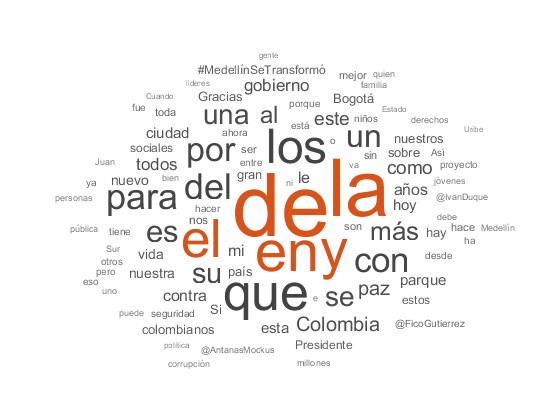

clear; clc; warning off
Files=dir; FileNames={}; c=1;
for k=3:length(Files)
   FileNames{c,1}=Files(k).name;
   c=c+1;
end

[temp1,temp2]=xlsread(FileNames{1});
fw=temp2(:,2);
fw=flip(fw); fw=fw(1:100);
AT=fw;

for i=2:1:length(FileNames)
    [temp1,temp2]=xlsread(FileNames{i});
    fw=temp2(:,2);
    fw=flip(fw); fw=fw(1:100);
    AT=cat(1,AT,fw);
end
wordcloud(AT);

ATF=cell2table(AT);
writetable(ATF,'DBTweets.xlsx')

